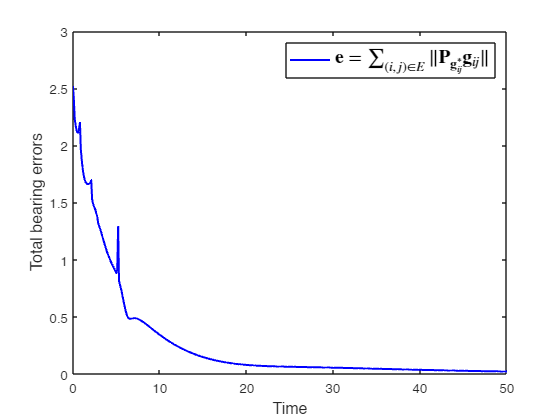

clear all;
clc;
global H d P21d P31d P32d P42d P52d P62d P43d P54d P74d P84d P65d ...
    P75d P96d Px6d P87d P97d Py8d Px9d Py9d Pzxd Pzyd
n = 12;
m = 21;
s = [1 1 2 2 2 2 3 4 4 4 5 5 6  6 7 7  8  9  9 10 11];
t = [2 3 3 4 5 6 4 5 7 8 6 7 9 10 8 9 11 10 11 12 12];
G = graph(s,t);
H = incidence(G)'*eye(n);
d = 2;
p1 = [3;0];
p2 = [2;1];
p3 = [2;-1];
p5 = [1;0];
p6 = [1;2];
p9 = [0;1];
px = [0;3];
pz = [-1;2];
p4 = [1;-2];
p7 = [0;-1];
p8 = [0;-3];
py = [-1;-2];
pd = [p1; p2; p3; p4; p5; p6; p7; p8; p9; px; py; pz];

zd = -kron(H,eye(d))*pd;
Zd = reshape(zd,d,length(H));
Gd = Zd./vecnorm(Zd);
gd = Gd(:);
g21d = Gd(:, 1); P21d = eye(2) - g21d*g21d';
g31d = Gd(:, 2); P31d = eye(2) - g31d*g31d';
g32d = Gd(:, 3); P32d = eye(2) - g32d*g32d';
g42d = Gd(:, 4); P42d = eye(2) - g42d*g42d';
g52d = Gd(:, 5); P52d = eye(2) - g52d*g52d';
g62d = Gd(:, 6); P62d = eye(2) - g62d*g62d';
g43d = Gd(:, 7); P43d = eye(2) - g43d*g43d';
g54d = Gd(:, 8); P54d = eye(2) - g54d*g54d';
g74d = Gd(:, 9); P74d = eye(2) - g74d*g74d';
g84d = Gd(:,10); P84d = eye(2) - g84d*g84d';
g65d = Gd(:,11); P65d = eye(2) - g65d*g65d';
g75d = Gd(:,12); P75d = eye(2) - g75d*g75d';
g96d = Gd(:,13); P96d = eye(2) - g96d*g96d';
gx6d = Gd(:,14); Px6d = eye(2) - gx6d*gx6d';
g87d = Gd(:,15); P87d = eye(2) - g87d*g87d';
g97d = Gd(:,16); P97d = eye(2) - g97d*g97d';
gy8d = Gd(:,17); Py8d = eye(2) - gy8d*gy8d';
gx9d = Gd(:,18); Px9d = eye(2) - gx9d*gx9d';
gy9d = Gd(:,19); Py9d = eye(2) - gy9d*gy9d';
gzxd = Gd(:,20); Pzxd = eye(2) - gzxd*gzxd';
gzyd = Gd(:,21); Pzyd = eye(2) - gzyd*gzyd';
P = blkdiag(P21d,P31d,P32d,P42d,P52d,P62d,P43d,P54d,P74d,P84d,P65d,P75d,P96d,Px6d,P87d,P97d,Py8d,Px9d,Py9d,Pzxd,Pzyd);
str1 = '#87CEFA';
str2 = '#FFB6C1';
str3 = '#C0C0C0';
str4 = '#006400';
color1 = sscanf(str1(2:end),'%2x%2x%2x',[1 3])/255;
color2 = sscanf(str2(2:end),'%2x%2x%2x',[1 3])/255;
color3 = sscanf(str3(2:end),'%2x%2x%2x',[1 3])/255;
color4 = sscanf(str4(2:end),'%2x%2x%2x',[1 3])/255;

rng(1)
x0 = [0;0;0;1.5;pd(5:end,1)+4*(rand(d*(n-2),1)-0.5)];

[t,x] = ode45(@formation, [0:0.1:50], x0);
r = x;
t_end = length(t);
na = 1;
tend1 = (floor(length(t)/100));
tend2 = length(t);
%r = r';
 Err1 = zeros(1,length(t));
 figure
 for i=1:length(t)
     q = r(i,:)';
     z = -kron(H,eye(d))*q;
     Z = reshape(z,d,length(H));
     G = Z./vecnorm(Z);
     g = G(:);
     Err1(1,i) = norm(P*g);
 end
 hold on
 plot(t,Err1(1,:),"LineWidth",1.5,"Color",'b')
 legend({'$\mathbf{e}=\sum_{(i,j) \in E} \|\mathbf{P}_{\mathbf{g}_{ij}^*} \mathbf{g}_{ij}\|$'}, "Interpreter", "latex", "FontSize", 14)
 xlabel('Time',"FontSize",12)
 ylabel('Total bearing errors',"FontSize",12)
 box on

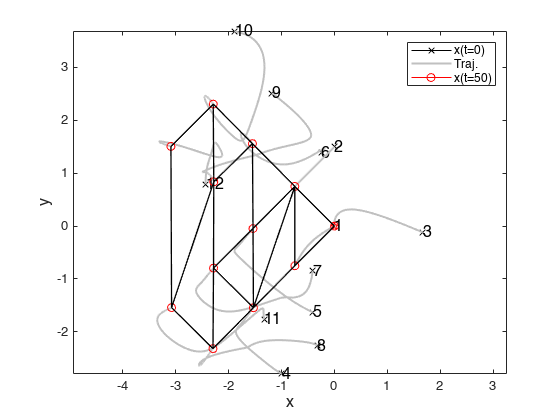

% Biểu diễn hệ
figure
hold on
for i=n:-1:1
 if i<=na
    plot(r(1,d*i-d+1),r(1,d*i-d+2),'r','Marker','pentagram');
 else
    plot(r(1,d*i-d+1),r(1,d*i-d+2),'k','Marker','x');
 end
 plot(r(:,d*i-d+1),r(:,d*i-d+2),"LineWidth",1.5,"Color",color3);
 % plot(r(tend1,d*i-d+1),r(tend1,d*i-d+2),"Color",'k','Marker','o');
 plot(r(tend2,d*i-d+1),r(tend2,d*i-d+2),"Color",'r','Marker','o');
 text(r(1,d*i-d+1),r(1,d*i-d+2),num2str(i),"FontSize",12);
end
 
% line([r(tend1,1), r(tend1,3)],  [r(tend1,2), r(tend1,4)], 'Color', 'k','LineWidth',1,'LineStyle','--'); % (1,2)
% line([r(tend1,1), r(tend1,5)],  [r(tend1,2), r(tend1,6)], 'Color', 'k','LineWidth',1,'LineStyle','--'); % (1,3)
% line([r(tend1,3), r(tend1,5)],  [r(tend1,4), r(tend1,6)], 'Color', 'k','LineWidth',1,'LineStyle','--'); % (2,3)
% line([r(tend1,3), r(tend1,7)],  [r(tend1,4), r(tend1,8)], 'Color', 'k','LineWidth',1,'LineStyle','--'); % (2,4)
% line([r(tend1,3), r(tend1,9)],  [r(tend1,4),r(tend1,10)], 'Color', 'k','LineWidth',1,'LineStyle','--'); % (2,5)
% line([r(tend1,3), r(tend1,11)], [r(tend1,4),r(tend1,12)], 'Color', 'k','LineWidth',1,'LineStyle','--'); % (2,6)
% line([r(tend1,5), r(tend1,7)],  [r(tend1,6), r(tend1,8)], 'Color', 'k','LineWidth',1,'LineStyle','--'); % (3,4)
% line([r(tend1,7), r(tend1,9)],  [r(tend1,8),r(tend1,10)], 'Color', 'k','LineWidth',1,'LineStyle','--'); % (4,5)
% line([r(tend1,7),r(tend1,13)],  [r(tend1,8),r(tend1,14)], 'Color', 'k','LineWidth',1,'LineStyle','--'); % (4,7)
% line([r(tend1,7),r(tend1,15)],  [r(tend1,8),r(tend1,16)], 'Color', 'k','LineWidth',1,'LineStyle','--'); % (4,8)
% line([r(tend1,9),r(tend1,11)], [r(tend1,10),r(tend1,12)], 'Color', 'k','LineWidth',1,'LineStyle','--'); % (5,6)
% line([r(tend1,9),r(tend1,13)], [r(tend1,10),r(tend1,14)], 'Color', 'k','LineWidth',1,'LineStyle','--'); % (5,7)
% line([r(tend1,11),r(tend1,17)],[r(tend1,12),r(tend1,18)], 'Color', 'k','LineWidth',1,'LineStyle','--'); % (6,9)
% line([r(tend1,11),r(tend1,19)],[r(tend1,12),r(tend1,20)], 'Color', 'k','LineWidth',1,'LineStyle','--'); % (6,10)
% line([r(tend1,13),r(tend1,15)],[r(tend1,14),r(tend1,16)], 'Color', 'k','LineWidth',1,'LineStyle','--'); % (7,8)
% line([r(tend1,13),r(tend1,17)],[r(tend1,14),r(tend1,18)], 'Color', 'k','LineWidth',1,'LineStyle','--'); % (7,9)
% line([r(tend1,15),r(tend1,21)],[r(tend1,16),r(tend1,22)], 'Color', 'k','LineWidth',1,'LineStyle','--'); % (8,11)
% line([r(tend1,17),r(tend1,19)],[r(tend1,18),r(tend1,20)], 'Color', 'k','LineWidth',1,'LineStyle','--'); % (9,10)
% line([r(tend1,17),r(tend1,21)],[r(tend1,18),r(tend1,22)], 'Color', 'k','LineWidth',1,'LineStyle','--'); % (9,11)
% line([r(tend1,23),r(tend1,19)],[r(tend1,24),r(tend1,20)], 'Color', 'k','LineWidth',1,'LineStyle','--'); % (10,12)
% line([r(tend1,23),r(tend1,21)],[r(tend1,24),r(tend1,22)], 'Color', 'k','LineWidth',1,'LineStyle','--'); % (11,12)

line([r(tend2,1), r(tend2,3)], [r(tend2,2), r(tend2,4)], 'Color', 'k','LineWidth',1,'LineStyle','-'); % (1,2)
line([r(tend2,1), r(tend2,5)], [r(tend2,2), r(tend2,6)], 'Color', 'k','LineWidth',1,'LineStyle','-'); % (1,3)
line([r(tend2,3), r(tend2,5)], [r(tend2,4), r(tend2,6)], 'Color', 'k','LineWidth',1,'LineStyle','-'); % (2,3)
line([r(tend2,3), r(tend2,7)], [r(tend2,4), r(tend2,8)], 'Color', 'k','LineWidth',1,'LineStyle','-'); % (2,4)
line([r(tend2,3), r(tend2,9)], [r(tend2,4), r(tend2,10)], 'Color','k','LineWidth',1,'LineStyle','-'); % (2,5)
line([r(tend2,3), r(tend2,11)],[r(tend2,4), r(tend2,12)], 'Color','k','LineWidth',1,'LineStyle','-'); % (2,6)
line([r(tend2,5), r(tend2,7)], [r(tend2,6), r(tend2,8)], 'Color', 'k','LineWidth',1,'LineStyle','-'); % (3,4)
line([r(tend2,7), r(tend2,9)], [r(tend2,8), r(tend2,10)], 'Color','k','LineWidth',1,'LineStyle','-'); % (4,5)
line([r(tend2,7), r(tend2,13)],[r(tend2,8), r(tend2,14)], 'Color','k','LineWidth',1,'LineStyle','-'); % (4,7)
line([r(tend2,7), r(tend2,15)],[r(tend2,8), r(tend2,16)], 'Color','k','LineWidth',1,'LineStyle','-'); % (4,8)
line([r(tend2,9), r(tend2,11)],[r(tend2,10),r(tend2,12)], 'Color','k','LineWidth',1,'LineStyle','-'); % (5,6)
line([r(tend2,9), r(tend2,13)],[r(tend2,10),r(tend2,14)], 'Color','k','LineWidth',1,'LineStyle','-'); % (5,7)
line([r(tend2,11),r(tend2,17)],[r(tend2,12),r(tend2,18)], 'Color','k','LineWidth',1,'LineStyle','-'); % (6,9)
line([r(tend2,11),r(tend2,19)],[r(tend2,12),r(tend2,20)], 'Color','k','LineWidth',1,'LineStyle','-'); % (6,10)
line([r(tend2,13),r(tend2,15)],[r(tend2,14),r(tend2,16)], 'Color','k','LineWidth',1,'LineStyle','-'); % (7,8)
line([r(tend2,13),r(tend2,17)],[r(tend2,14),r(tend2,18)], 'Color','k','LineWidth',1,'LineStyle','-'); % (7,9)
line([r(tend2,15),r(tend2,21)],[r(tend2,16),r(tend2,22)], 'Color','k','LineWidth',1,'LineStyle','-'); % (8,11)
line([r(tend2,17),r(tend2,19)],[r(tend2,18),r(tend2,20)], 'Color','k','LineWidth',1,'LineStyle','-'); % (9,10)
line([r(tend2,17),r(tend2,21)],[r(tend2,18),r(tend2,22)], 'Color','k','LineWidth',1,'LineStyle','-'); % (9,11)
line([r(tend2,23),r(tend2,19)],[r(tend2,24),r(tend2,20)], 'Color','k','LineWidth',1,'LineStyle','-'); % (10,12)
line([r(tend2,23),r(tend2,21)],[r(tend2,24),r(tend2,22)], 'Color','k','LineWidth',1,'LineStyle','-'); % (11,12)

legend({'x(t=0)','Traj.','x(t=50)'})
xlabel('x',"FontSize",12)
ylabel('y',"FontSize",12)
axis equal
box on

% grid on

function dx = formation(~,x)
global H d P21d P31d P32d P42d P52d P62d P43d P54d P74d P84d P65d ...
    P75d P96d Px6d P87d P97d Py8d Px9d Py9d Pzxd Pzyd

z = -kron(H,eye(d))*x;
Z = reshape(z,d,length(H));
G = Z./vecnorm(Z);
g21 = G(:, 1);
g31 = G(:, 2);
g32 = G(:, 3);
g42 = G(:, 4);
g52 = G(:, 5);
g62 = G(:, 6);
g43 = G(:, 7);
g54 = G(:, 8);
g74 = G(:, 9);
g84 = G(:,10);
g65 = G(:,11);
g75 = G(:,12);
g96 = G(:,13);
gx6 = G(:,14);
g87 = G(:,15);
g97 = G(:,16);
gy8 = G(:,17);
gx9 = G(:,18);
gy9 = G(:,19);
gzx = G(:,20);
gzy = G(:,21);
dx1 = [0;0];
dx2 = P21d*g21;
dx3 = P31d*g31 + P32d*g32;
dx4 = P42d*g42 + P43d*g43;
dx5 = P52d*g52 + P54d*g54;
dx6 = P62d*g62 + P65d*g65;
dx7 = P74d*g74 + P75d*g75;
dx8 = P84d*g84 + P87d*g87;
dx9 = P96d*g96 + P97d*g97;
dxx = Px6d*gx6 + Px9d*gx9;
dxy = Py8d*gy8 + Py9d*gy9;
dxz = Pzxd*gzx + Pzyd*gzy;
dx = 1*[dx1;dx2;dx3;dx4;dx5;dx6;dx7;dx8;dx9;dxx;dxy;dxz];

end